# **Lab 5 - Principle Component Analysis**

Look at the documentation of the Matlab function eig. This function produces a diagonal matrix D of eigenvalues and a full matrix V whose columns are the corresponding eigenvectors so that X*V = V*D.

### Question 1 Build the bi-variate time series X = [x1;x2], composed by 100 observation, as follows:

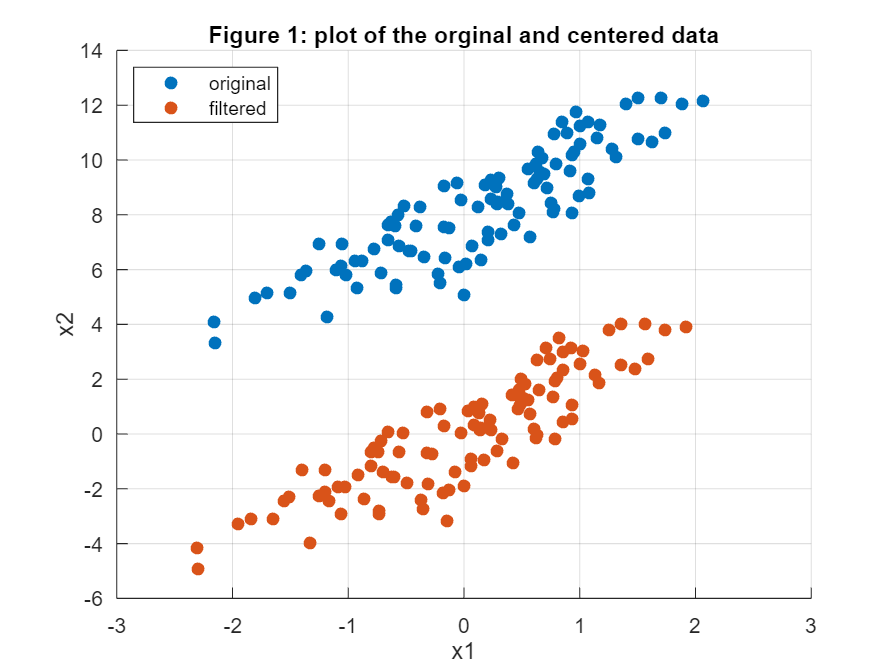

c1 = [2 8];
x1 = randn(1,100);
x2 = polyval(c1,x1)+randn(size(x1));
X = [x1;x2];

%center each time series with respect to its mean, as follows:
[~, n] = size(X);
mx = mean(X,2);
Xo = X - mx*ones(1, n);


%Plot the original and the centered data on the same figure, so as to generate a figure like Fig. 1.
figure
scatter(x1, x2, 'filled', 'DisplayName','original')
hold on
scatter(Xo(1,:),Xo(2,:),'filled', 'DisplayName','filtered')
% axis equal
grid on
title('Figure 1: plot of the orginal and centered data')
legend('-DynamicLegend','Location', 'northwest')
xlabel('x1')
ylabel('x2')

### Question 2 

Apply function eig to the covariance matrix Rx of Xo so as to achieve its eigenvalue decompo�sition, as follows: 

N = length(Xo);
Rx = Xo*Xo'/(N-1) ;
[U, D] = eig(Rx);

Verify that matrix U is orthogonal and look at matrix D: what do you observe and why?

%to check for orthogonality, just need to multiply matrix by its transpose
%and supposed to get identity matrix

U*U'

ans =     1.0000         0
         0    1.0000


U

U =    -0.9279    0.3729
    0.3729    0.9279


D

D =     0.1710         0
         0    5.0951


A: (NFM)

The columns of U are the eigenvectors corresponding to the diagonal values of D. We see that indeed we only have two eigenvectors and eigenvalues because we only have two dimentional data. We will have n eigenvectors/values for n-Dim data.

As the matrix mulitplication with its transpose (U*U') yields a diagonal matrix of ones (which is equal to the identity matrix), we find that matrix U is indeed orhthogonal. For matrix D we find that the value 6.06 implies a higher importance of the direction of variable x2, we can confirm this by looking at the spread of x2 in figure 1.

### Question3

In the course we have seen that the PCA model can be described as: X = AZ. Generate the matrix of principal components Z and the transfer matrix A, collecting the corresponding eigenvectors, by exploiting the solution for the EVD model presented in the course, and assuming the covariance matrix of Z to be Rz = ZZT /(N−1) = I (with I being the identity matrix, and N the number of samples in the multivariate signal Z). 

NOTE: 

*to solve the indeterminacy on the order of the components, reorganize the eigenvalues in matrix D and the corresponding eigenvectors in matrix U in decreasing order (use functions fliplr and flipud appropriately)*

%flip the matrices in decreasing order
U = fliplr(U)  

U =     0.3729   -0.9279
    0.9279    0.3729


D = fliplr(flipud(D)) %can do the other way around as well flipud(fliplr(D))

D =     5.0951         0
         0    0.1710


%𝐴=𝑈𝐷^(1/2)
A=U*sqrt(D)

A =     0.8416   -0.3837
    2.0945    0.1542


%𝑍=𝐴^(−1) 𝑋=𝐷^(−1/2) 𝑈^𝑇 𝑋
Z=inv(A)*Xo

Z =    -0.0652    0.3440   -1.5749    1.2737   -1.0473   -0.7745    0.3349    1.4276    0.4348    1.3772    1.8620   -0.7571    1.2285   -1.5461   -0.8523   -1.3687    1.4188   -0.9042   -0.9653    0.1546   -0.7334    0.9814   -1.2579   -0.4566   -0.2011   -0.8097   -0.7567   -1.1128   -0.3238   -0.2146   -2.3963    0.2778   -0.7301    0.9214    0.0246   -1.6712    0.1163   -1.3170   -0.3865    1.9252    0.7775    0.1856    1.8803   -1.2634    0.5934    0.9312    0.4631    0.5299   -0.9565   -0.6798
    1.5652    1.2821    1.3417   -0.7457   -1.3447   -1.7181   -1.4975    0.4468    0.7150    0.7796   -0.4632    1.9796    0.0620    0.8962   -1.5519   -0.2330    1.2633   -1.5114    0.7092    0.1023   -0.0497    0.0533    1.2791   -1.1717   -1.2059   -0.5019    0.7242   -0.2022    0.1050    1.3777    0.7241    1.4348    1.5160    0.7296    0.0996    1.4093   -0.1354   -0.9951    1.2261   -0.7805   -0.0060   -1.1813    0.5782   -0.8678   -1.1338   -0.0191   -0.2035   -0.1158    0.5606    0

%Or 
Z2=D^(-1/2)*U'*Xo

Z2 =    -0.0652    0.3440   -1.5749    1.2737   -1.0473   -0.7745    0.3349    1.4276    0.4348    1.3772    1.8620   -0.7571    1.2285   -1.5461   -0.8523   -1.3687    1.4188   -0.9042   -0.9653    0.1546   -0.7334    0.9814   -1.2579   -0.4566   -0.2011   -0.8097   -0.7567   -1.1128   -0.3238   -0.2146   -2.3963    0.2778   -0.7301    0.9214    0.0246   -1.6712    0.1163   -1.3170   -0.3865    1.9252    0.7775    0.1856    1.8803   -1.2634    0.5934    0.9312    0.4631    0.5299   -0.9565   -0.6798
    1.5652    1.2821    1.3417   -0.7457   -1.3447   -1.7181   -1.4975    0.4468    0.7150    0.7796   -0.4632    1.9796    0.0620    0.8962   -1.5519   -0.2330    1.2633   -1.5114    0.7092    0.1023   -0.0497    0.0533    1.2791   -1.1717   -1.2059   -0.5019    0.7242   -0.2022    0.1050    1.3777    0.7241    1.4348    1.5160    0.7296    0.0996    1.4093   -0.1354   -0.9951    1.2261   -0.7805   -0.0060   -1.1813    0.5782   -0.8678   -1.1338   -0.0191   -0.2035   -0.1158    0.5606    

%Compute A*Z
A*Z

ans =    -0.6554   -0.2023   -1.8402    1.3580   -0.3655    0.0073    0.8563    1.0301    0.0916    0.8600    1.7448   -1.3967    1.0101   -1.6450   -0.1219   -1.0625    0.7095   -0.1812   -1.0844    0.0908   -0.5982    0.8055   -1.5494    0.0653    0.2934   -0.4889   -0.9147   -0.8590   -0.3128   -0.7092   -2.2946   -0.3167   -1.1961    0.4955   -0.0175   -1.9472    0.1499   -0.7266   -0.7957    1.9197    0.6567    0.6094    1.3607   -0.7304    0.9344    0.7910    0.4678    0.4905   -1.0201   -0.6998
    0.1047    0.9182   -3.0917    2.5527   -2.4008   -1.8871    0.4705    3.0590    1.0209    3.0047    3.8285   -1.2806    2.5825   -3.1000   -2.0243   -2.9026    3.1665   -2.1268   -1.9124    0.3395   -1.5437    2.0637   -2.4375   -1.1369   -0.6070   -1.7732   -1.4733   -2.3620   -0.6620   -0.2372   -4.9073    0.8030   -1.2954    2.0423    0.0669   -3.2831    0.2228   -2.9119   -0.6205    3.9120    1.6275    0.2067    4.0275   -2.7799    1.0682    1.9475    0.9385    1.0921   -1.9169   

### Question 4

Given the expressions for A and Z at the previous question, generate the following figures: 

-  Fig. 2: plot the centered data together with the first and second eigenvectors, using the function vectarrow (e.g.: vectarrow([0 0],A(:,1)’)). Notice the orthogonality of their directions! 

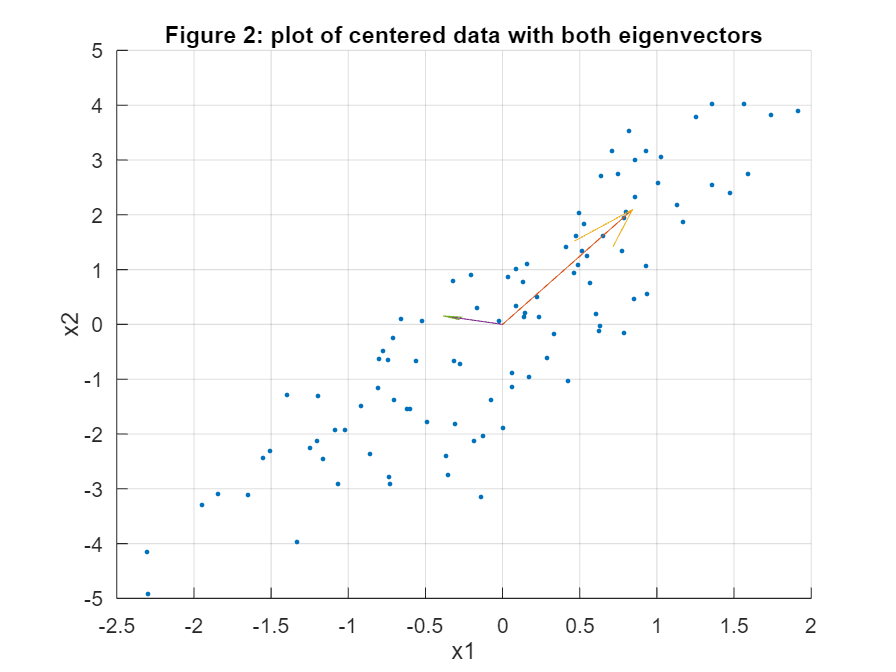

figure

% scatter(x1, x2, 'filled', 'DisplayName','original')
scatter(Xo(1,:),Xo(2,:), 5, 'filled', 'DisplayName','filtered')
hold on
xlabel('x1')
ylabel('x2')

vectarrow([0 0],A(:,1)') %first eigenvector
hold on

vectarrow([0 0],A(:,2)') %second eigenvector
hold off
title('Figure 2: plot of centered data with both eigenvectors')

%Check how much the variable covers/contributes to the variance of the data
%NFM!!!

*The length of the vector is an indication of how "important" that axis is in describing the distribution of the data—more precisely, it is a measure of the variance of the data when projected onto that axis. The projection of each data point onto the principal axes are the "principal components" of the data.*

lenV1 = sqrt(power(A(1,1),2)+power(A(2,1),2));
lenV2 = sqrt(power(A(1,2),2)+power(A(2,2),2));

varPC1 = lenV1/(lenV1+lenV2)

varPC1 = 0.8452

varPC2 = 1-varPC1

varPC2 = 0.1548

*We find that the PC1 covers about varPC1 = 86.12% of the variance in the data. While PC2 covers the remaining varPC2 = 13.88%.*

-  Fig. 3: plot the second principal component versus the first, what do you notice? 

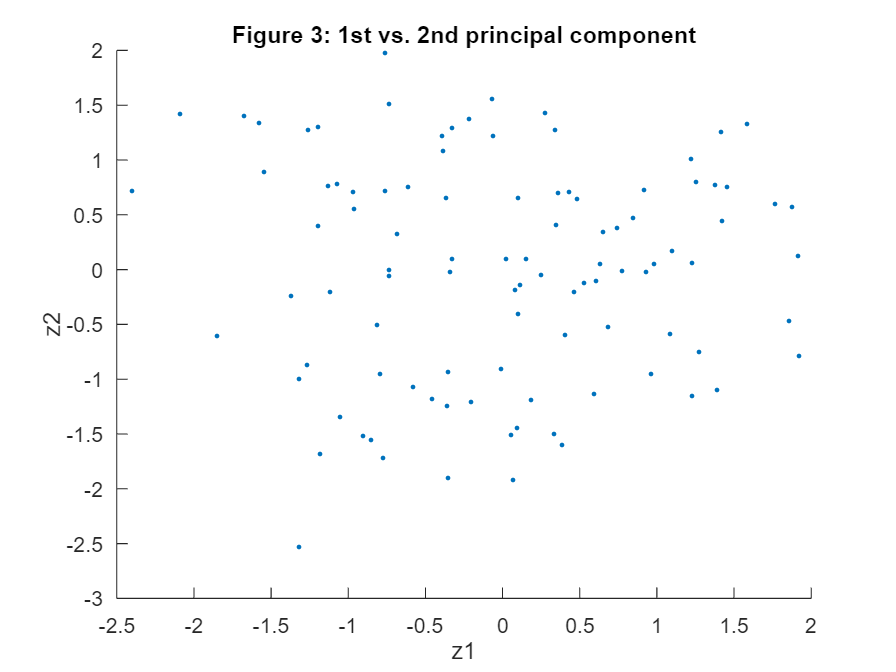

figure
scatter(Z(1,:),Z(2,:),5,'filled')
title('Figure 3: 1st vs. 2nd principal component')
xlabel('z1')
ylabel('z2')

What do you notice?

NFM

**A:*** In the affine transformation, we can see that neither component really splits the data into clusters. *

-  Fig. 4: reconstruct the original (uncentered) data by using the first principal component only, and make a plot of the original data and their reconstruction.

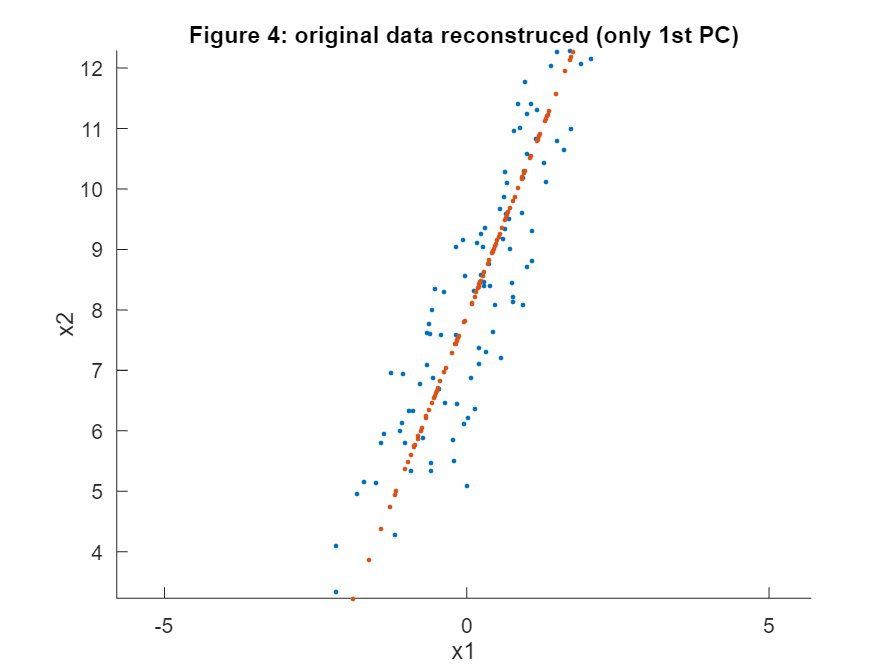

%For instance, if we would like to reconstruct the original (centered) data Xo by only using the first three principal components, then:
 % 
 %            X3 = A(:,1:3)*pinv(A(:,1:3))*Xo;
 % 
 % and then add the means back

recon1= A(:,1)*pinv(A(:,1))*Xo;
% recon2= A(:,2)*pinv(A(:,2))*Xo;

%adding the mean
recon1 = recon1+ mx;
% recon2 = recon2+mx;

%plot everything
figure
scatter(x1, x2,5, 'filled', 'DisplayName','original')

xlabel('x1')
ylabel('x2')
hold on
scatter(recon1(1,:),recon1(2,:), 5, "filled")
%No need the second PC
% hold on
% scatter(recon2(1,:),recon2(2,:), 5, "filled")

axis equal
title('Figure 4: original data reconstruced (only 1st PC)')

What do you obtain? Why? Try to comment on the result of this projection.

A: NFM

In PCA, higher-ranked principal components typically capture less significant modes of variation. By using only the first principal component, we are essentially projecting the data onto a one-dimensional subspace, losing some information present in the second dimension. The quality of the reconstruction depends on how much variability is captured by the chosen components. This exercise demonstrates the trade-off between dimensionality reduction and preserving the original data's complexity. In practical terms, using a single principal component for reconstruction may result in a simplified representation but may not fully reproduce the intricacies of the original dataset.

ME: But because we know that it accounts for 86% of the variance, then it is relatively alright. 

### Question 5

Repeat questions 2 to 4, but this time without centering the data with respect to their mean values. Try to explain the main differences which can be noticed in each figure. 

**q2**

N = length(X);
Rx = X*X'/(N-1);
[U, D] = eig(Rx)

U =    -0.9992    0.0402
    0.0402    0.9992


D =     0.7594         0
         0   73.2781


%orthogonality
U*U'

ans =      1     0
     0     1


**q3**

%flip the matrices in decreasing order
U = fliplr(U);  
D = fliplr(flipud(D)); %can do the other way around as well flipud(fliplr(D))
%𝐴=𝑈𝐷^(1/2)
A=U*sqrt(D);
%𝑍=𝐴^(−1) 𝑋=𝐷^(−1/2) 𝑈^𝑇 𝑋
Z=inv(A)*Xo;

%Compute A*Z
A*Z

ans =    -0.6554   -0.2023   -1.8402    1.3580   -0.3655    0.0073    0.8563    1.0301    0.0916    0.8600    1.7448   -1.3967    1.0101   -1.6450   -0.1219   -1.0625    0.7095   -0.1812   -1.0844    0.0908   -0.5982    0.8055   -1.5494    0.0653    0.2934   -0.4889   -0.9147   -0.8590   -0.3128   -0.7092   -2.2946   -0.3167   -1.1961    0.4955   -0.0175   -1.9472    0.1499   -0.7266   -0.7957    1.9197    0.6567    0.6094    1.3607   -0.7304    0.9344    0.7910    0.4678    0.4905   -1.0201   -0.6998
    0.1047    0.9182   -3.0917    2.5527   -2.4008   -1.8871    0.4705    3.0590    1.0209    3.0047    3.8285   -1.2806    2.5825   -3.1000   -2.0243   -2.9026    3.1665   -2.1268   -1.9124    0.3395   -1.5437    2.0637   -2.4375   -1.1369   -0.6070   -1.7732   -1.4733   -2.3620   -0.6620   -0.2372   -4.9073    0.8030   -1.2954    2.0423    0.0669   -3.2831    0.2228   -2.9119   -0.6205    3.9120    1.6275    0.2067    4.0275   -2.7799    1.0682    1.9475    0.9385    1.0921   -1.9169   

**q4**

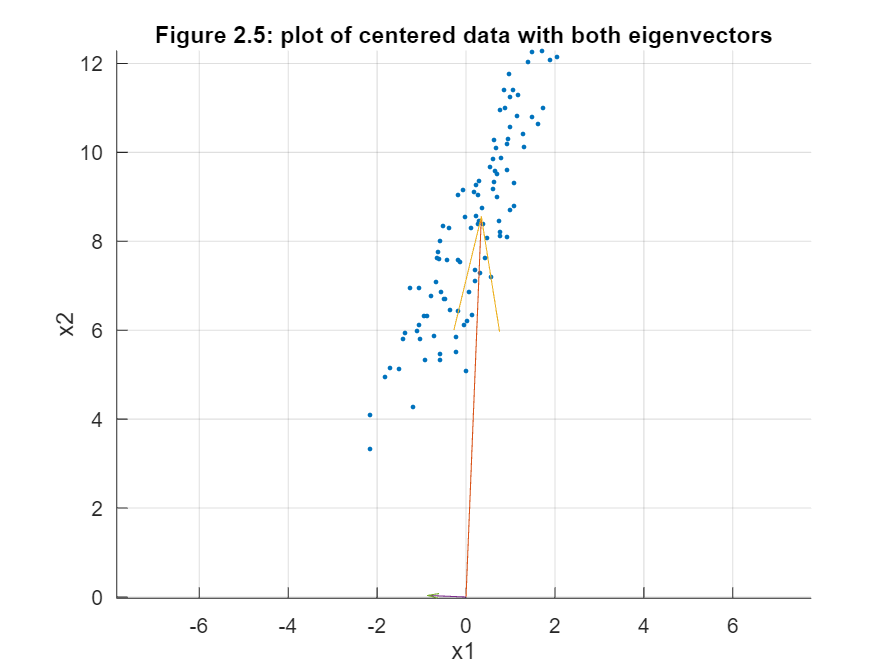

figure

scatter(X(1,:),X(2,:), 5, 'filled', 'DisplayName','filtered')
hold on
xlabel('x1')
ylabel('x2')

vectarrow([0 0],A(:,1)') %first eigenvector
hold on

vectarrow([0 0],A(:,2)') %second eigenvector
hold off
title('Figure 2.5: plot of centered data with both eigenvectors')
axis equal

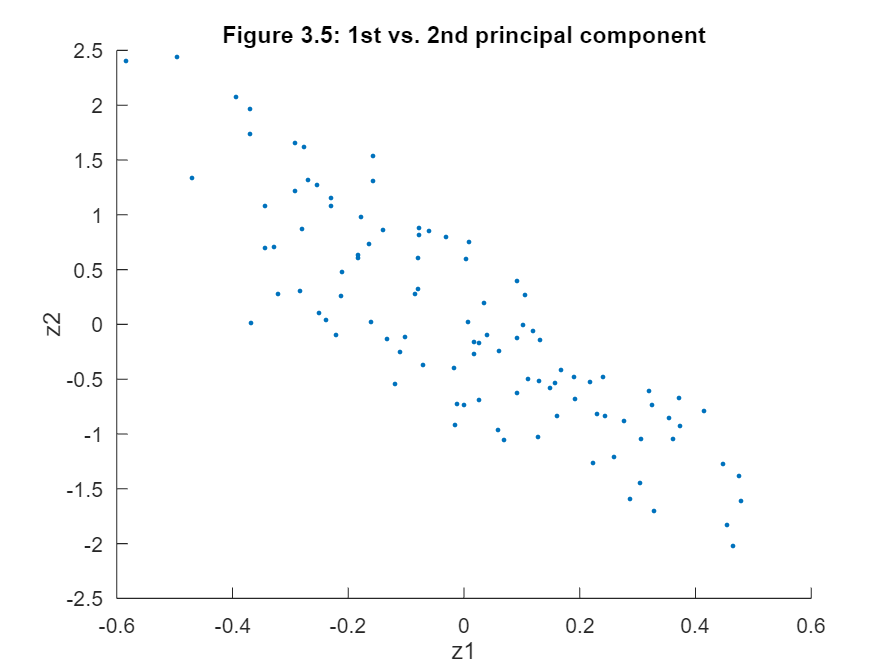

figure
scatter(Z(1,:),Z(2,:),5,'filled')
title('Figure 3.5: 1st vs. 2nd principal component')
xlabel('z1')
ylabel('z2')

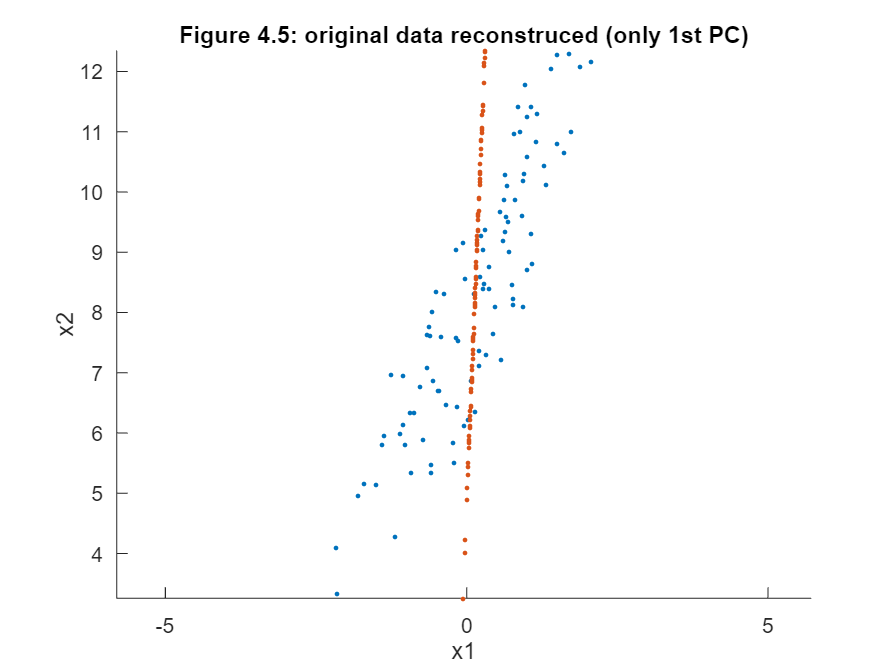


recon1= A(:,1)*pinv(A(:,1))*Xo;
% recon2= A(:,2)*pinv(A(:,2))*Xo;

%adding the mean
recon1 = recon1+ mx;
% recon2 = recon2+mx;

%plot everything
figure
scatter(x1, x2,5, 'filled', 'DisplayName','original')

xlabel('x1')
ylabel('x2')
hold on
scatter(recon1(1,:),recon1(2,:), 5, "filled")
%No need the second PC
% hold on
% scatter(recon2(1,:),recon2(2,:), 5, "filled")

axis equal
title('Figure 4.5: original data reconstruced (only 1st PC)')

### Question 6

Load the signal in data.mat. The signal data is a 12-lead (12 channels) ECG recording sampled at 1KHz (samples on rows and leads on columns). The signal has been acquired from a patient affected by atrial fibrillation.

%clear evrything to be able to do PCA again on new data
clear
%load data
load data.mat

%ECG recording sampled at 1KHz
fs= 1000

fs = 1000


%data is our nezw x
X = data

X =     3.9964    3.9985    3.9998    4.0005    4.0005    4.0002    3.9997    3.9993    3.9989    3.9988    3.9988    3.9991    3.9998    3.9974    3.9949    3.9924    3.9901    3.9880    3.9860    3.9843    3.9827    3.9813    3.9800    3.9787    3.9775    3.9763    3.9751    3.9738    3.9725    3.9712    3.9699    3.9688    3.9677    3.9668    3.9661    3.9657    3.9656    3.9657    3.9662    3.9670    3.9680    3.9692    3.9706    3.9720    3.9735    3.9750    3.9763    3.9775    3.9784    3.9791
   -0.0278   -0.0187   -0.0105   -0.0041    0.0002    0.0020    0.0014   -0.0015   -0.0062   -0.0120   -0.0183   -0.0242   -0.0133   -0.0142   -0.0153   -0.0166   -0.0180   -0.0194   -0.0208   -0.0221   -0.0232   -0.0242   -0.0250   -0.0256   -0.0259   -0.0260   -0.0259   -0.0255   -0.0250   -0.0244   -0.0237   -0.0229   -0.0220   -0.0212   -0.0205   -0.0198   -0.0194   -0.0190   -0.0189   -0.0190   -0.0193   -0.0198   -0.0205   -0.0214   -0.0225   -0.0238   -0.0251   -0.0266   -0.0281   -0

%transpose the data to be in correct format
X=X'

X =     3.9964   -0.0278   -0.0175    0.0370   -0.0097   -0.0174    6.5367    0.1530    0.1901    0.0227   -0.0968   -0.1782
    3.9985   -0.0187   -0.0115    0.0276   -0.0082   -0.0109    6.5286    0.1103    0.1370    0.0153   -0.0708   -0.1310
    3.9998   -0.0105   -0.0063    0.0178   -0.0059   -0.0055    6.5194    0.0680    0.0846    0.0086   -0.0445   -0.0827
    4.0005   -0.0041   -0.0022    0.0087   -0.0034   -0.0016    6.5104    0.0311    0.0388    0.0033   -0.0209   -0.0393
    4.0005    0.0002    0.0004    0.0016   -0.0011    0.0007    6.5028    0.0037    0.0049   -0.0002   -0.0031   -0.0062
    4.0002    0.0020    0.0014   -0.0025    0.0005    0.0013    6.4979   -0.0108   -0.0133   -0.0017    0.0068    0.0124
    3.9997    0.0014    0.0008   -0.0031    0.0012    0.0005    6.4965   -0.0110   -0.0136   -0.0012    0.0074    0.0139
    3.9993   -0.0015   -0.0011    0.0002    0.0006   -0.0015    6.4991    0.0034    0.0041    0.0012   -0.0014   -0.0022
    3.9989   -0.0062   -0.00

%prepare data for pca
[m, n] = size(X);
mx = mean(X,2);
Xo = X - mx*ones(1, n)

Xo =     3.1140   -0.9102   -0.8998   -0.8454   -0.8921   -0.8998    5.6543   -0.7293   -0.6923   -0.8596   -0.9792   -1.0605
    3.1180   -0.8992   -0.8921   -0.8529   -0.8887   -0.8914    5.6481   -0.7702   -0.7436   -0.8652   -0.9513   -1.0115
    3.1213   -0.8891   -0.8849   -0.8608   -0.8845   -0.8841    5.6409   -0.8105   -0.7940   -0.8699   -0.9230   -0.9613
    3.1237   -0.8808   -0.8790   -0.8681   -0.8802   -0.8784    5.6336   -0.8457   -0.8380   -0.8735   -0.8977   -0.9161
    3.1252   -0.8751   -0.8750   -0.8737   -0.8765   -0.8747    5.6275   -0.8716   -0.8705   -0.8756   -0.8785   -0.8816
    3.1257   -0.8725   -0.8731   -0.8770   -0.8740   -0.8732    5.6234   -0.8854   -0.8878   -0.8762   -0.8677   -0.8621
    3.1254   -0.8730   -0.8736   -0.8775   -0.8732   -0.8739    5.6221   -0.8854   -0.8880   -0.8755   -0.8670   -0.8605
    3.1242   -0.8765   -0.8761   -0.8749   -0.8744   -0.8765    5.6241   -0.8716   -0.8709   -0.8738   -0.8764   -0.8772
    3.1226   -0.8825   -0.8

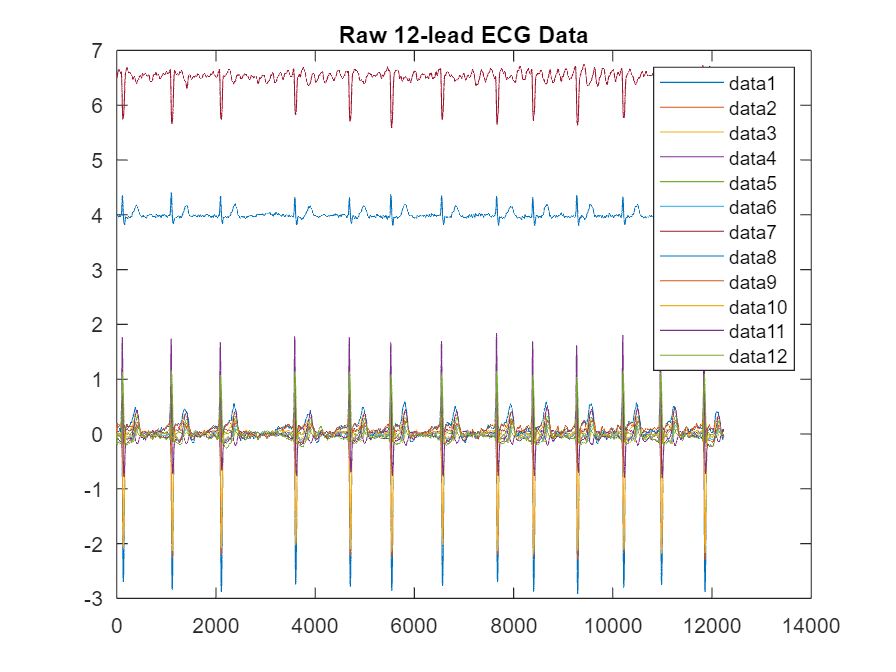

%plot raw data for visaulization
figure
plot((1:length(X)),X)
title('Raw 12-lead ECG Data')
legend()

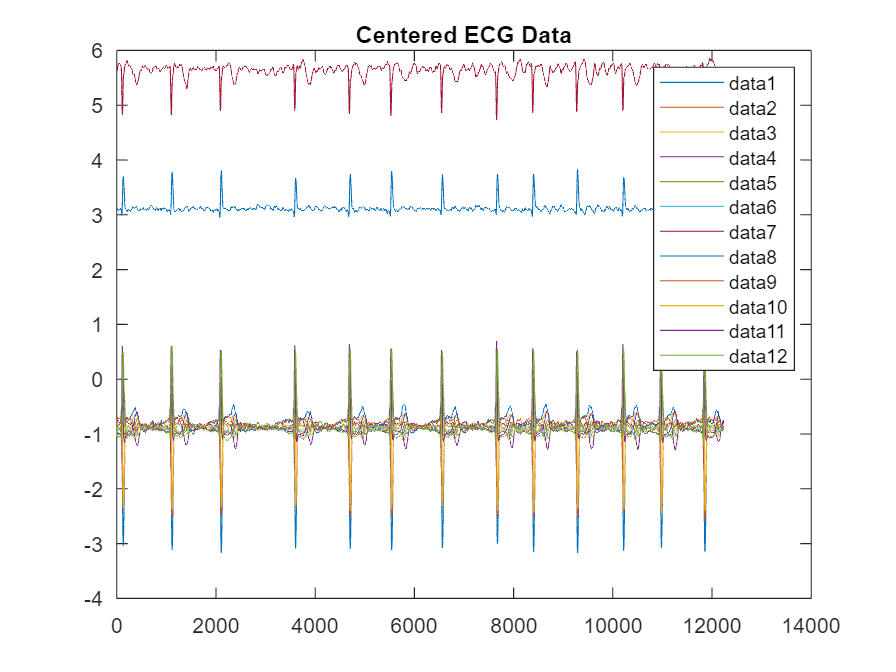


%plot centered data
figure
plot((1:length(X)),Xo)
title('Centered ECG Data')
legend()

-  Consider data. Perform PCA on data, by focusing on their variance, by means of Singular Value Decomposition (look at the documentation of the Matlab function svd, and consider using [U, S, V] = svd(data,’econ’);), to find out A and Z (based on the SVD model presented in class)

%from lecture
[U,S,V] = svd(X,'econ');
N = length(X);
A = U*S/sqrt(N-1);
Z = sqrt(N-1)*V';

A*Z

ans =     3.9964   -0.0278   -0.0175    0.0370   -0.0097   -0.0174    6.5367    0.1530    0.1901    0.0227   -0.0968   -0.1782
    3.9985   -0.0187   -0.0115    0.0276   -0.0082   -0.0109    6.5286    0.1103    0.1370    0.0153   -0.0708   -0.1310
    3.9998   -0.0105   -0.0063    0.0178   -0.0059   -0.0055    6.5194    0.0680    0.0846    0.0086   -0.0445   -0.0827
    4.0005   -0.0041   -0.0022    0.0087   -0.0034   -0.0016    6.5104    0.0311    0.0388    0.0033   -0.0209   -0.0393
    4.0005    0.0002    0.0004    0.0016   -0.0011    0.0007    6.5028    0.0037    0.0049   -0.0002   -0.0031   -0.0062
    4.0002    0.0020    0.0014   -0.0025    0.0005    0.0013    6.4979   -0.0108   -0.0133   -0.0017    0.0068    0.0124
    3.9997    0.0014    0.0008   -0.0031    0.0012    0.0005    6.4965   -0.0110   -0.0136   -0.0012    0.0074    0.0139
    3.9993   -0.0015   -0.0011    0.0002    0.0006   -0.0015    6.4991    0.0034    0.0041    0.0012   -0.0014   -0.0022
    3.9989   -0.0062   -0.

U*S*V'

ans =     3.9964   -0.0278   -0.0175    0.0370   -0.0097   -0.0174    6.5367    0.1530    0.1901    0.0227   -0.0968   -0.1782
    3.9985   -0.0187   -0.0115    0.0276   -0.0082   -0.0109    6.5286    0.1103    0.1370    0.0153   -0.0708   -0.1310
    3.9998   -0.0105   -0.0063    0.0178   -0.0059   -0.0055    6.5194    0.0680    0.0846    0.0086   -0.0445   -0.0827
    4.0005   -0.0041   -0.0022    0.0087   -0.0034   -0.0016    6.5104    0.0311    0.0388    0.0033   -0.0209   -0.0393
    4.0005    0.0002    0.0004    0.0016   -0.0011    0.0007    6.5028    0.0037    0.0049   -0.0002   -0.0031   -0.0062
    4.0002    0.0020    0.0014   -0.0025    0.0005    0.0013    6.4979   -0.0108   -0.0133   -0.0017    0.0068    0.0124
    3.9997    0.0014    0.0008   -0.0031    0.0012    0.0005    6.4965   -0.0110   -0.0136   -0.0012    0.0074    0.0139
    3.9993   -0.0015   -0.0011    0.0002    0.0006   -0.0015    6.4991    0.0034    0.0041    0.0012   -0.0014   -0.0022
    3.9989   -0.0062   -0.

-  How could you obtain an approximation of the cardiac beat (the peaks in the ECG signals) by exploiting the results at the previous point? Remember how PCA can be used to reduce the dimensionality of a dataset by compressing the information in few components describing most of the variance in the original dataset. 2 

%Need to see which pc explains best the data and the can reduce the dim to
%get a good approximation (depending on how much each pc explains the
%variance ofc)

%for some reason, I have to recompute the centered data:
[m, n] = size(data);
mx = mean(data,2);  
centeredX = data- mx*ones(1, n);

%Redo before with centered data:
[U,S,V] = svd(centeredX','econ');
N = length(centeredX);
A = U*S/sqrt(N-1);
Z = sqrt(N-1)*V';

%Do eigenvalue decomposition
%Here we just recreate an eigenvalue decomposition, with Y the eigenvector matrix and O the Eigenvalue diagonal matrix
% Rx = Xo*Xo'/(N-1);
% [vector, value] = eig(Rx) %for some reason this takes agaes to compute so
% leave it

eigenVals= S*S/(N-1)

eigenVals =     0.5840         0         0         0         0         0         0         0         0         0         0         0
         0    0.1600         0         0         0         0         0         0         0         0         0         0
         0         0    0.0100         0         0         0         0         0         0         0         0         0
         0         0         0    0.0058         0         0         0         0         0         0         0         0
         0         0         0         0    0.0027         0         0         0         0         0         0         0
         0         0         0         0         0    0.0008         0         0         0         0         0         0
         0         0         0         0         0         0    0.0005         0         0         0         0         0
         0         0         0         0         0         0         0    0.0002         0         0         0         0
         0         0

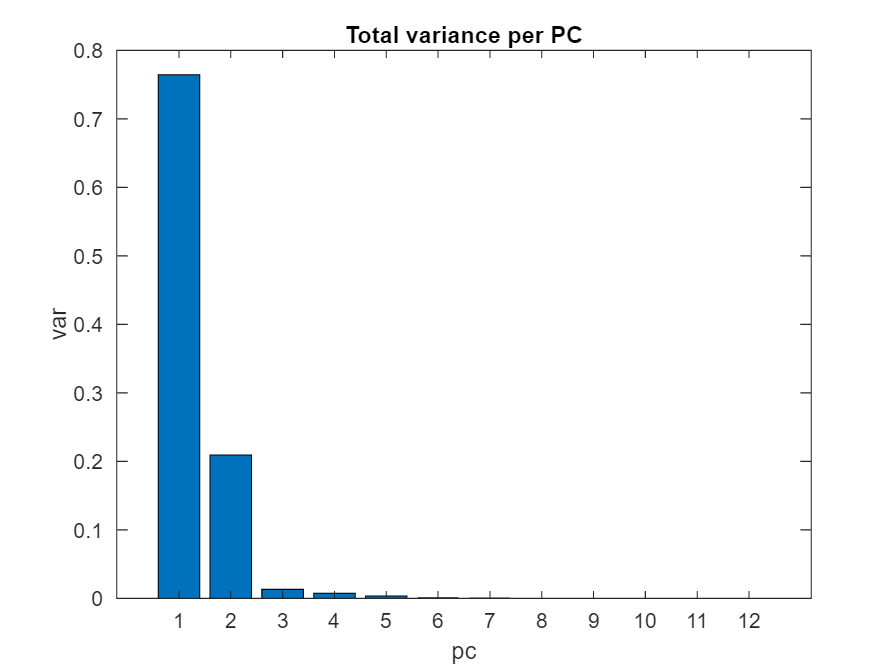

%C = (U*power(S,2)*U')/(N-1);
variance = diag(eigenVals) ./ sum(eigenVals(:));
% investigate the variance
figure
bar(variance)
title("Total variance per PC")
xlabel('pc')
ylabel('var')

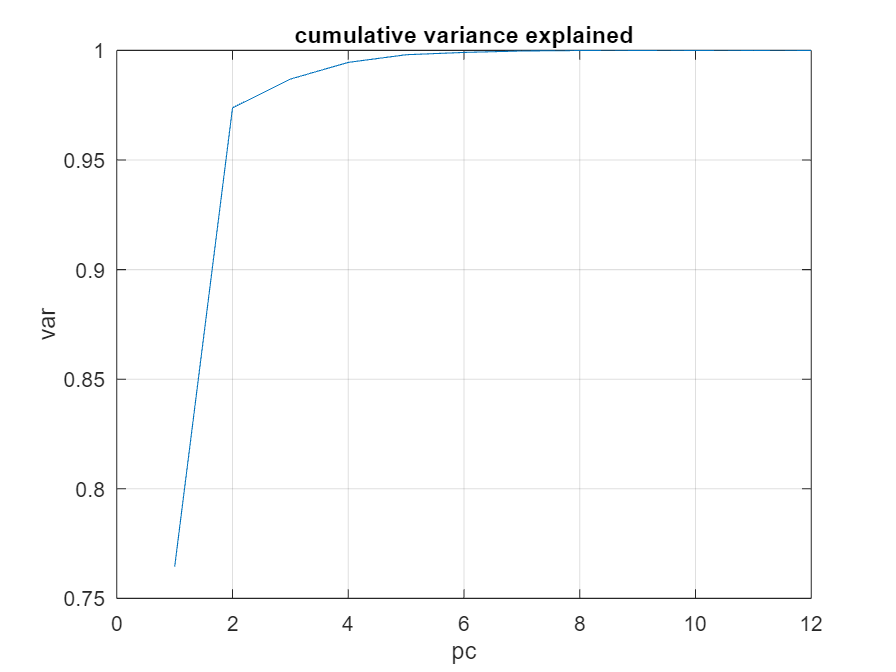

cumVar = cumsum(variance);
figure
plot(cumVar)
title("cumulative variance explained")
xlabel('pc')
ylabel('var')
grid on

**Looking at both graphs, it is clear that the 2 first pc can be used to reconstruct the data. The elbow in the send graph proves the first bar graph.**

% Lets come back to...

Remember how PCA can be used to reduce the dimensionality of a dataset by compressing the information in few components describing most of the variance in the original dataset. 

% mdata = mean(data,2);
% 
% data0 = data - mdata;
% [U,S,V] = svd(data0,'econ');
% 
% A = sqrt(length(data)-1)^(-1)*(U*S);
% 
ecg_rec = A(:,1:3)*pinv(A(:,1:3))*Xo;

figure
plot((1:length(Xo)),Xo(1,:))

Error using plot
Vectors must be the same length.

hold on
plot((1:length(ecg_rec)),ecg_rec(1,:))
hold off
legend('data','reconstructed PC1-3')
title('Reconstruction of the QRS-T complex')

-  It is known that atrial fibrillation is characterized by a dominant frequency in the range [4, 10] Hz. With this knowledge, propose a way both to estimate the value of the dominant frequency of the atrial fibrillation in the ECG recordings under analysis, and to reconstruct the original ECG recordings only by using the PCs with a dominant peak in the range [4, 10] Hz 